# **Ubicación de polos por respuesta en el tiempo**

Considere el caso donde se desea diseñar un controlador para el siguiente polinomio característico deseado,


$$p{\left(s\right)}=\ s^2 +2\zeta \omega_n +{\omega_n }^2$$


Con las siguientes especificaciones:

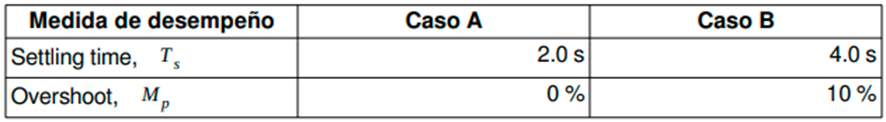

**1)** ¿Cuáles son los valores de ωn, ζ para el caso A? ¿Dónde se ubican los polos del polinomio deseado? Grafique la respuesta al escalón.

A partir de las siguientes ecuaciones podemos observar cómo se                         calculan las medidas de desempeño en función de los parámetros del sistema:

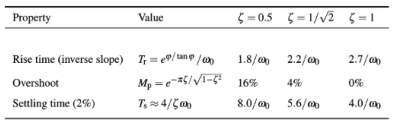

Entonces podemos decir que:


$$\zeta =\frac{\mathrm{ln}\left(M_p \right)}{\sqrt{\pi^2 +{\left(\mathrm{ln}\left(M_p \right)\right)}^2 }}$$



$$\omega_n \approx \frac{4}{\zeta T_s }$$


Para el caso A:


$$\begin{array}{l}
\zeta =1\\
\omega_n =2\;\mathrm{rad}/s
\end{array}$$


close all; clear all; clc;
zeta = 1; % Amortiguamiento.
wn = 2; % Frecuencia natural.
Ha = tf([1],[1 2*zeta*wn wn^2]) % Función de transferencia.

Ha =
 
        1
  -------------
  s^2 + 4 s + 4
 
Continuous-time transfer function.



% Polos de la función de transferencia:
disp(pole(Ha))

    -2
    -2



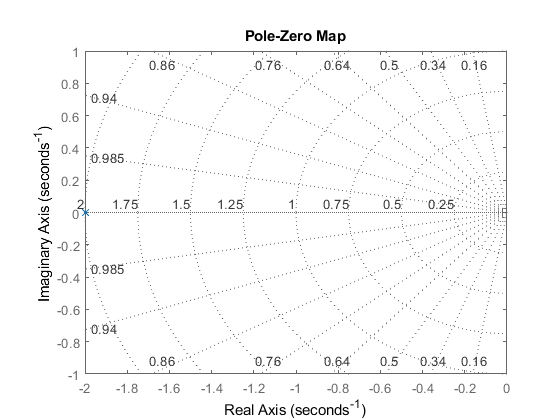

pzmap(Ha) % Graficamos los polos y ceros en el plano de Laplace.
grid on

ha = stepplot(Ha) % Respuesta al escalón unitario.


ha =

	resppack.timeplot



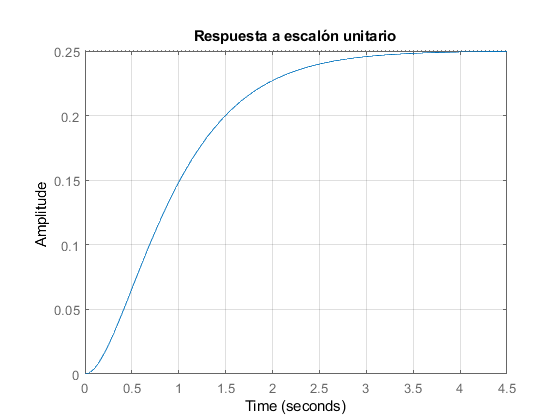

setoptions(ha,'Grid','on');
title('Respuesta a escalón unitario')

sa = stepinfo(Ha);
disp(sa) % Ploteamos los parámetros del sistema.

        RiseTime: 1.6790
    SettlingTime: 2.9170
     SettlingMin: 0.2252
     SettlingMax: 0.2498
       Overshoot: 0
      Undershoot: 0
            Peak: 0.2498
        PeakTime: 4.6900



Dado que no se cumple la especificación del settling time, realizamos un bucle iterativo para encontrar el valor solución.

settlingtime = 2;
while(abs(double(sa.SettlingTime)-settlingtime)>0.01)
    wn = wn + 0.01;
    Ha = tf(1,[1 2*zeta*wn wn^2]);
    sa = stepinfo(Ha);
end
disp('La nueva frecuencia calculada es:')

La nueva frecuencia calculada es:


disp(wn)

    2.9100



Ha = tf(1,[1 2*zeta*wn wn^2])

Ha =
 
           1
  --------------------
  s^2 + 5.82 s + 8.468
 
Continuous-time transfer function.



% Polos de la función de transferencia:
disp(pole(Ha))

  -2.9100 + 0.0000i
  -2.9100 - 0.0000i



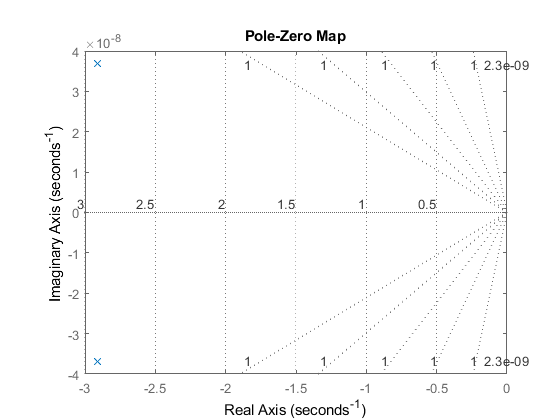

pzmap(Ha) % Graficamos los polos y ceros en el plano de Laplace.
grid on

ha = stepplot(Ha) % Respuesta al escalón unitario.


ha =

	resppack.timeplot



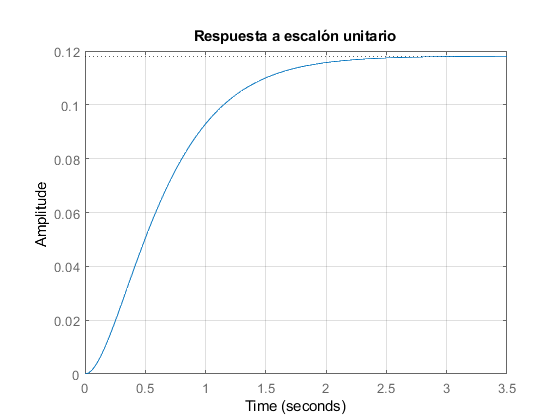

setoptions(ha,'Grid','on');
title('Respuesta a escalón unitario')

sa = stepinfo(Ha);
disp(sa) % Ploteamos los parámetros del sistema

        RiseTime: 1.1541
    SettlingTime: 2.0048
     SettlingMin: 0.1065
     SettlingMax: 0.1181
       Overshoot: 0
      Undershoot: 0
            Peak: 0.1181
        PeakTime: 4.0988



**2)** ¿Cuáles son los valores de ωn, ζ para el caso B? ¿Dónde se ubican los polos del polinomio deseado? Grafique la respuesta al escalón.

Para el caso B:


$$\begin{array}{l}
\zeta =0,591\\
\omega_n =1\ldotp 692\;\mathrm{rad}/s
\end{array}$$


zeta = 0.591; % Amortiguamiento.
wn = 1.692; % Frecuencia natural.
Hb = tf([1],[1 2*zeta*wn wn^2]) % Función de transferencia.

Hb =
 
          1
  -----------------
  s^2 + 2 s + 2.863
 
Continuous-time transfer function.



% Polos de la función de transferencia:
disp(pole(Hb))

  -1.0000 + 1.3649i
  -1.0000 - 1.3649i



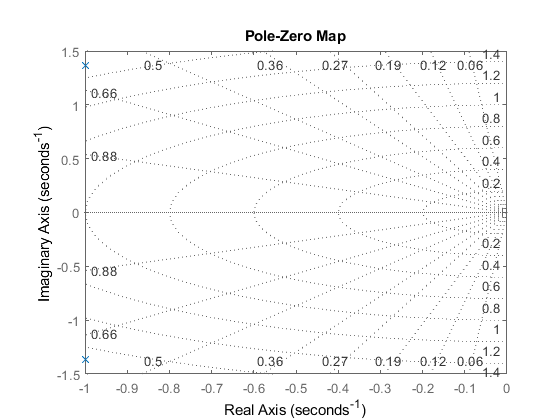

pzmap(Hb) % Graficamos los polos y ceros en el plano de Laplace.
grid on

hb = stepplot(Hb) % Respuesta al escalón unitario.


hb =

	resppack.timeplot



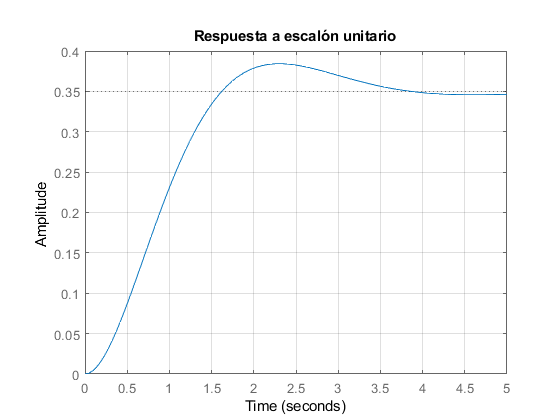

setoptions(hb,'Grid','on');
title('Respuesta a escalón unitario')

sb = stepinfo(Hb);
disp(sb) % Ploteamos los parámetros del sistema.

        RiseTime: 1.0837
    SettlingTime: 3.5021
     SettlingMin: 0.3154
     SettlingMax: 0.3843
       Overshoot: 10.0093
      Undershoot: 0
            Peak: 0.3843
        PeakTime: 2.3026



Dado que no se cumple la especificación del settling time, realizamos un bucle iterativo para encontrar el valor solución.

settlingtime = 4;
while(abs(double(sb.SettlingTime)-settlingtime)>0.01)
    wn = wn - 0.01;
    Hb = tf(1,[1 2*zeta*wn wn^2]);
    sb = stepinfo(Hb);
end
disp('La nueva frecuencia calculada es:')

La nueva frecuencia calculada es:


disp(wn)

    1.4820



Hb = tf(1,[1 2*zeta*wn wn^2])

Hb =
 
            1
  ---------------------
  s^2 + 1.752 s + 2.196
 
Continuous-time transfer function.



% Polos de la función de transferencia:
disp(pole(Hb))

  -0.8759 + 1.1955i
  -0.8759 - 1.1955i



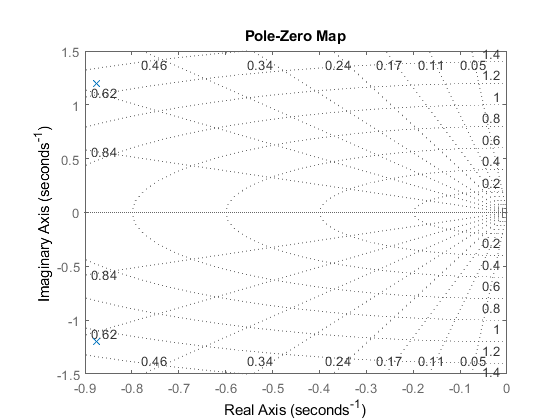

pzmap(Hb) % Graficamos los polos y ceros en el plano de Laplace.
grid on

hb = stepplot(Hb) % Respuesta al escalón unitario.


hb =

	resppack.timeplot



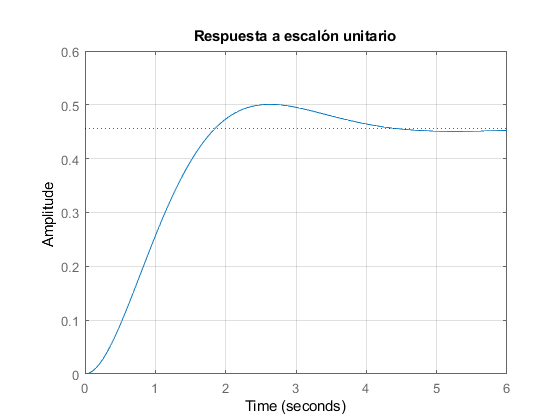

setoptions(hb,'Grid','on');
title('Respuesta a escalón unitario')

sa = stepinfo(Hb);
disp(sb) % Ploteamos los parámetros del sistema

        RiseTime: 1.2373
    SettlingTime: 3.9983
     SettlingMin: 0.4111
     SettlingMax: 0.5009
       Overshoot: 10.0093
      Undershoot: 0
            Peak: 0.5009
        PeakTime: 2.6289

